%% This is the script for ESE 6190 Homework 3 Ex2
clear all
clc
%% Basic Deifinition
% Define system matrixcs:
A = [0.77, -0.35; 0.49, 0.91];
% Define input matrixcs:
B = [0.04;0.15];
% Horizon Length
N = 50;
% Define weight matrices:
Q = [500,0; 0,100];
R = 1;
P_N = [1500, 0; 0, 100];
% Define initial state:
x0 = [1;-1];


%% (1) Solution via Batch appoach
[U_b,J_b] = UFHLQOC_Batch(A, B, N, Q, R, P_N, x0,"analytical");

%% (2) Solution via Batch appoach, but use quadrprog
[U_bopt,J_bopt] = UFHLQOC_Batch(A, B, N, Q, R, P_N, x0,"optimize");


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


%% verify the result
flag_U = norm(U_b-U_bopt)<=1e-8;
flag_J = norm(J_b-J_bopt)<=1e-8;

%% (3) Solution via Recursive approach
[U_r,J_r,F_r] = UFHLQOC_Recursive(A, B, N, Q, R, P_N, x0);
%% verify the result
flag_U_br = norm(U_b-U_r)<=1e-8;
flag_J_br = norm(J_b-J_r)<=1e-8;


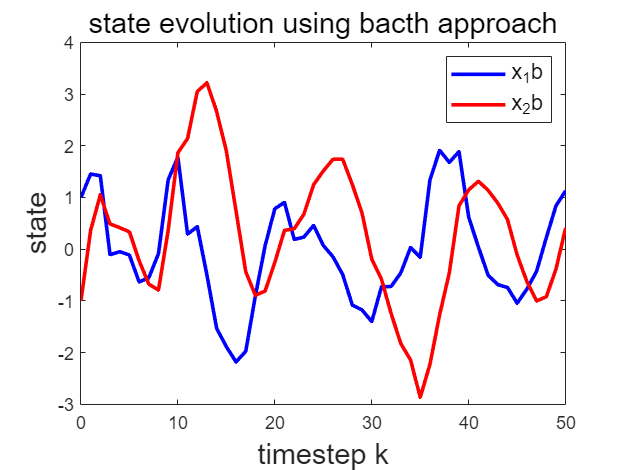

%% (4) Simulate the disturbed dynamics
% Define distrubance process
rng(0)
n = size(A, 1);
D = [0.1;0.1];
w = sqrt(10)*randn(N);
x_b = zeros(n,N);
x_r = zeros(n,N);
% Simulate the system
for i = 0:N-1
    if i == 0
        x_b(:, i+1) = disturbed_system(x0, U_b(1), w(1), A, B, D);
        x_r(:, i+1) = disturbed_system(x0, F_r(1,:)*x0, w(1), A, B, D);
    else
        x_b(:, i+1) = disturbed_system(x_b(:,i), U_b(i+1), w(i+1), A, B, D);
        x_r(:, i+1) = disturbed_system(x_r(:,i), F_r(i+1,:)*x_r(:,i), w(i+1), A, B, D);
    end
end
x_b = [x0,x_b];
x_r = [x0,x_r];
t = 0:1:N;
% plot the figure
figure
plot(t, x_b(1,:), '-b', 'LineWidth', 2)
hold on
plot(t, x_b(2,:), '-r', 'LineWidth', 2)
legend('x_1b','x_2b',FontSize=12)
title('state evolution using bacth approach',FontSize=16)
xlabel('timestep k',FontSize=16)
ylabel('state',FontSize=16)

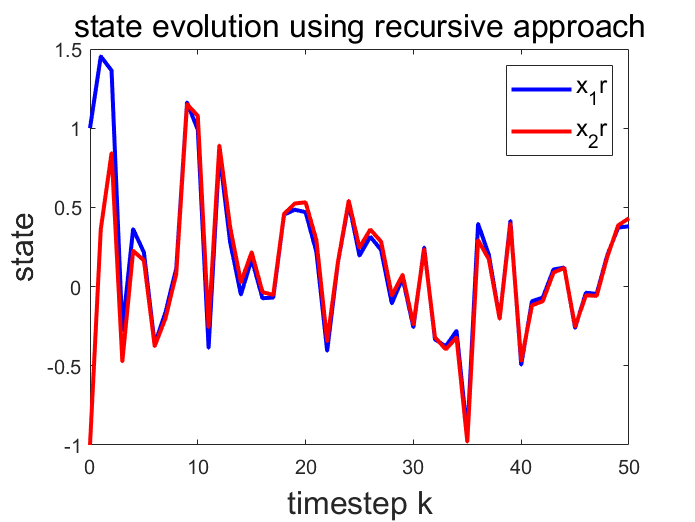

figure
plot(t, x_r(1,:), '-b', 'LineWidth', 2)
hold on
plot(t, x_r(2,:), '-r', 'LineWidth', 2)
legend('x_1r','x_2r',FontSize=12)
title('state evolution using recursive approach',FontSize=16)
xlabel('timestep k',FontSize=16)
ylabel('state',FontSize=16)

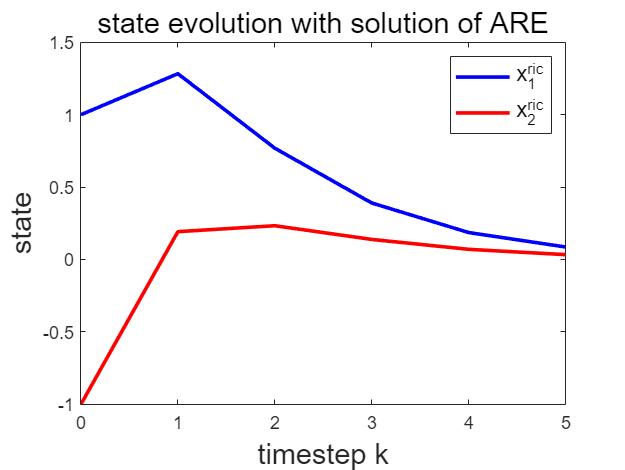

%% (5) Redesign the controller
% choose the terminal weight to be the solution of ARE
N = 5;
[P_ric,L_ric,G_ric] = idare(A,B,Q,R,0,eye(size(A)));
P_lya = dlyap(A,Q);
[U_ric,J_ric] = UFHLQOC_Batch(A, B, N, Q, R, P_ric, x0,"analytical");
[U_lya,J_lya] = UFHLQOC_Batch(A, B, N, Q, R, P_lya, x0,"analytical");
n = size(A, 1);
x_ric = zeros(n,N);
x_lya = zeros(n,N);
% Simulate the system
for i = 0:N-1
    if i == 0
        x_ric(:, i+1) = disturbed_system(x0, U_ric(1), 0, A, B, 0);
        x_lya(:, i+1) = disturbed_system(x0, U_lya(1), 0, A, B, 0);
    else
        x_ric(:, i+1) = disturbed_system(x_ric(:,i), U_ric(i+1), 0, A, B, 0);
        x_lya(:, i+1) = disturbed_system(x_lya(:,i), U_lya(i+1), 0, A, B, 0);
    end
end
x_ric = [x0,x_ric];
x_lya = [x0,x_lya];
t = 0:1:N;
% plot the figure
figure
plot(t, x_ric(1,:), '-b', 'LineWidth', 2)
hold on
plot(t, x_ric(2,:), '-r', 'LineWidth', 2)
legend('x^{ric}_1','x^{ric}_2',FontSize=12)
title('state evolution with solution of ARE',FontSize=16)
xlabel('timestep k',FontSize=16)
ylabel('state',FontSize=16)

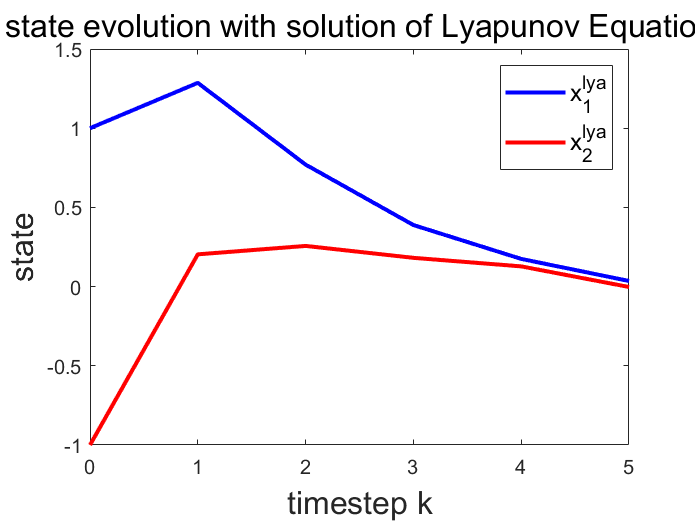

figure
plot(t, x_lya(1,:), '-b', 'LineWidth', 2)
hold on
plot(t, x_lya(2,:), '-r', 'LineWidth', 2)
legend('x^{lya}_1','x^{lya}_2',FontSize=12)
title('state evolution with solution of Lyapunov Equation',FontSize=16)
xlabel('timestep k',FontSize=16)
ylabel('state',FontSize=16)

function [U,J] = UFHLQOC_Batch(A, B, N, Q, R, P_N, x0, mode)
    %% This is the function used to solve the unconstrained finitie time
    %% linear quadratic optimal control via batch approach
    %% input:
    %  A: system matrix; B: Input matrix; N: control horizon;
    %  Q,R: weight matrices for states and inputs, respectively;
    %  P_N: terminal cost weight matrix; x0: initial condition
    %  mode: whether to use anylytical method or optimization method.
    %% output:
    %  U: the optimal control sequence U=[u0; u1; ...; uN-1];
    %  J: the optimal cost J=x0'*P0*x0
    
    % first, rollout the dynamics to get Sx and Su:
    n = size(A, 1);
    m = size(B, 2);
    Sx = zeros((N+1)*n, n);
    Su = zeros((N+1)*n, N*m);
    for i = 0:N
        Sx(i*n+1:(i+1)*n, 1:n) = A^i;
        for j = 0:N-1
            Su(i*n+1:(i+1)*n, j*m+1:(j+1)*m) = (i-j-1>=0)*A^(i-j-1)*B;
        end
    end
    % Then, get the stack-up weight matrices and rearrage as quadratic form
    I = eye(N);
    Q_bar = kron(I, Q);
    Q_bar(end+1:end+n, end+1:end+n) = P_N;
    R_bar = kron(I, R);
    H = Su'*Q_bar*Su + R_bar;
    F = Sx'*Q_bar*Su;
    % Calculte the optimal controller and optimal cost
    if mode == "analytical"
        U = -H^-1*F'*x0;
        J = U'*H*U + 2*x0'*F*U + x0'*Sx'*Q_bar*Sx*x0;
    elseif mode == "optimize"
        [U,J] = quadprog(2*H,2*F'*x0);
        J = J + x0'*Sx'*Q_bar*Sx*x0;
    end

end
%% functions for recursive approach
function [U,J,F] = UFHLQOC_Recursive(A, B, N, Q, R, P_N, x0)
    %% This is the function used to solve the unconstrained finitie time
    %% linear quadratic optimal control via recursive approach
    %% input:
    %  A: system matrix; B: Input matrix; N: control horizon;
    %  Q,R: weight matrices for states and inputs, respectively;
    %  P_N: terminal cost weight matrix; x0: initial condition
    %% output:
    %  U: the optimal control sequence U=[u0; u1; ...; uN-1];
    %  J: the optimal cost J=x0'*P*x0
    %  F: the optimal gain matrices sequence F = [F0; F1; ...; FN-1]

    % Start from the last time step k=N-1 to the initial state;
    n = size(A, 1);
    m = size(B, 2);
    U = zeros(N, m);
    F = zeros(N*m,n);
    P = zeros(N*n,n);
    J = zeros(N,1);
    for i = N-1:-1:0
        if i == N-1
            P_prev = P_N;
            F_curr = -(B'*P_prev*B+R)^(-1)*B'*P_prev*A;
            F(i*m+1:(i+1)*m,1:n) = F_curr;
            P_curr = A'*P_prev*A + Q + A'*P_prev*B*F_curr;
            P(i*n+1:(i+1)*n,1:n) = P_curr;
        else 
            P_prev = P((i+1)*n+1:(i+2)*n,1:n);
            F_curr = -(B'*P_prev*B+R)^(-1)*B'*P_prev*A;
            F(i*m+1:(i+1)*m,1:n) = F_curr;
            P_curr = A'*P_prev*A + Q + A'*P_prev*B*F_curr;
            P(i*n+1:(i+1)*n,1:n) = P_curr;
        end
    end
    for i = 0:N-1
        if i == 0
            U(i*m+1:(i+1)*m) = F(i*m+1:(i+1)*m,1:n)*x0;
            x = disturbed_system(x0,F(i*m+1:(i+1)*m,1:n)*x0,0,A,B,0);
        else
            U(i*m+1:(i+1)*m) = F(i*m+1:(i+1)*m,1:n)*x;
            x = disturbed_system(x,F(i*m+1:(i+1)*m,1:n)*x,0,A,B,0);
        end
    end
    J = x0'*P(1:n,1:n)*x0;
end

function xp = disturbed_system(xk, uk, wk, A, B, D)
    %% This is the function used to simulate single-step dynamics of the diturbed system
    %% input:
    %  A: system matrix; B: Input matrix; D: Disturbance matrix;
    %  xk: current state, uk: current input, wk: guassian white noise
    xp = A*xk + B*uk + D*wk;
end

    
